# Monte Carlo Design with Armington

Start with Armington model with $a_{ij}$ set to 1's.

clc; clear; % clear data and command window

load 'armington_data.mat';  % load data for 30 countries

w = ones(S,1); % initial value for w

tolerance = 1; % initial value for tolerance
               % needs to be greater than do loop
update = 0.3; % update is weight of new_w for next iteration's w
              % practical limit of 0.5
a_ij = ones(S,S);

while tolerance > 0.00001
   
    Y = w.*L;
    
    P =  sum(( a_ij.*repmat(A.^(sigma-1),1,S) .* ...
        (tau_ij.*repmat(w,1,S)).^(1-sigma) ),1)'.^(1./(1-sigma));
    
    X = repmat(A.^(sigma-1),1,S).* repmat(w.^(1-sigma),1,S) .* a_ij .* ...
        tau_ij.^(1-sigma) .* repmat( (Y.*P.^(sigma-1))', S,1);
    
    new_w = sum(X,2)./L;
    
    new_w = new_w./new_w(1); % numeraire country is first entry
    
    tolerance = (w-new_w)'*(w-new_w); % could also use sum of squares
    % try to stay close to something nice and boring and well known
    
    %disp(['tolerance = ', num2str(tolerance)]); % literally watch tolerance   
    
    w = w.*(1-update) + new_w.*update; % weighted average to update w
    % w = new_w may make system unstable
    
end
t_cmt = toc;

Now store results of contraction mapping. exp_true is exporter FE, imp_true is importer FE, k_true is bilateral trade costs, and true trade flows is X_true

exp_true = (sigma-1)*log(A)+(1-sigma)*log(w);

imp_true = log(Y)+(sigma-1)*log(P);

k_true = (1-sigma)*log(tau_ij);

X = reshape(X,S*S,1);

producing *observable* trade values $Trade = X_{ij}+\epsilon_{ij}$, where $\epsilon_{ij}$ has 0 mean with currently a normal distribution of std dev (sigma_trade) 2.

sigma_trade = 2;

Trade = X + normrnd(0,sigma_trade,S*S,1);
Trade = max(0,Trade);
disp(Trade);

   1.0e+03 *

    0.0025
    0.0038
    0.0021
         0
         0
    0.0052
    0.0044
    0.0053
    0.0204
    0.0068
         0
         0
    0.0018
    0.0063
    0.0041
    0.0018
    0.0071
    0.0128
         0
    0.0039
         0
    0.0016
         0
    0.0088
    0.0004
    0.0001
    0.0010
    0.0018
    0.0087
    0.0036
    0.0017
    0.1576
    0.0044
    0.0011
    0.0054
    0.0125
    0.0157
    0.0068
    0.0560
    0.0059
    0.0116
    0.0021
    0.0852
    0.0600
    0.0094
    0.0034
    0.0198
    0.0052
    0.0369
    0.0018
    0.0068
    0.0173
    0.0021
    0.3880
    0.0129
    0.0139
    0.0383
    0.0328
    0.0699
    0.0014
    0.0025
    0.0168
    0.0474
         0
    0.0203
    0.0048
    0.0025
    0.0188
    0.0727
    0.0149
    0.0043
    0.0063
    0.0475
    0.0010
    0.0192
    0.0116
    0.0706
    0.0071
    0.0112
    0.0028
    0.0028
    0.0133
         0
    0.0141
    0.0058
    0.0073
    0.0038
    0.0457
    0.0073
    0.0

and similarly *observable* distance related to trade costs

sigma_tau = 1;
distance = reshape(k_true./(1-sigma),S*S,1) + ...
    normrnd(0,sigma_tau,S*S,1);
disp(distance);

    0.6873
    0.5058
    1.7553
    0.9778
    0.7506
    0.0707
   -0.8082
   -0.2976
    1.0901
   -1.7574
    1.1354
   -1.4262
    0.5426
   -0.3000
    0.9252
    1.1318
    3.1960
    0.4702
    0.6742
    0.7090
    0.8981
   -0.2979
    0.9187
    0.5069
    3.2117
    2.0831
    0.3898
    1.8120
   -1.9229
    1.3121
    0.7940
   -1.2510
    2.4542
    0.6186
    0.3304
    2.0538
    1.3841
   -0.0233
    1.3352
    0.3998
    0.1184
   -0.8575
   -0.6875
    0.2262
    1.5336
    0.6566
    1.6254
    1.0086
   -0.4660
    2.2200
    1.6645
    0.4713
    2.9290
    0.1515
    1.8405
    0.2619
    1.1045
    2.1093
    0.7576
    1.7609
    2.2057
   -0.4310
    1.0130
    1.2603
    1.5449
    3.1290
    0.8891
    1.3013
    1.5771
    0.2619
   -0.9948
    1.5979
    0.3110
   -0.4877
    0.3835
    0.6024
    1.8843
   -0.4158
    1.0599
   -1.1698
    1.3572
    0.2771
   -0.1264
   -0.0345
   -0.2909
    0.1104
   -0.9442
    1.7402
   -0.6128
   -0.1905
    1.8387

declare the exporter FE and importer FE.  since we're not including a constant term, we can keep all of the importer FE.  but we have to drop one of the exporter FE  due to perfect multicolinearity.

exp_fe = repmat(eye(S,S),S,1);
exp_fe(:,1)=[]; 
imp_fe = kron(eye(S,S),ones(S,1)); 

Now we run OLS

XX = [exp_fe(Trade~=0,:) imp_fe(Trade~=0,:) distance(Trade~=0,:)];
YY = log(Trade(Trade~=0));
ols_results = fitlm(XX,YY,'linear','Intercept',false);
OLS = ols_results.Coefficients(:,1:2);
OLS = table2array(OLS);
disp(ols_results);


Linear regression model:
    y ~ [Linear formula with 60 terms in 60 predictors]

Estimated Coefficients:
           Estimate       SE        tStat       pValue  
           ________    ________    _______    __________

    x1       1.6049     0.29881     5.3711    1.0467e-07
    x2      0.59814     0.30705      1.948      0.051784
    x3      -1.0665     0.34105    -3.1271     0.0018341
    x4       1.5999     0.29888     5.3529    1.1538e-07
    x5       1.5028     0.29899     5.0262    6.2709e-07
    x6      0.69738     0.30411     2.2932      0.022114
    x7      0.37752     0.30143     1.2524        0.2108
    x8       1.8109     0.29894     6.0578    2.1894e-09
    x9      0.58989     0.30714  

Now to estimate with PPML

[coeff_PPML, dev, stats]= glmfit([exp_fe imp_fe distance],...
    Trade,'Poisson','constant','off');
PPML = [coeff_PPML stats.se];


Checking for bias

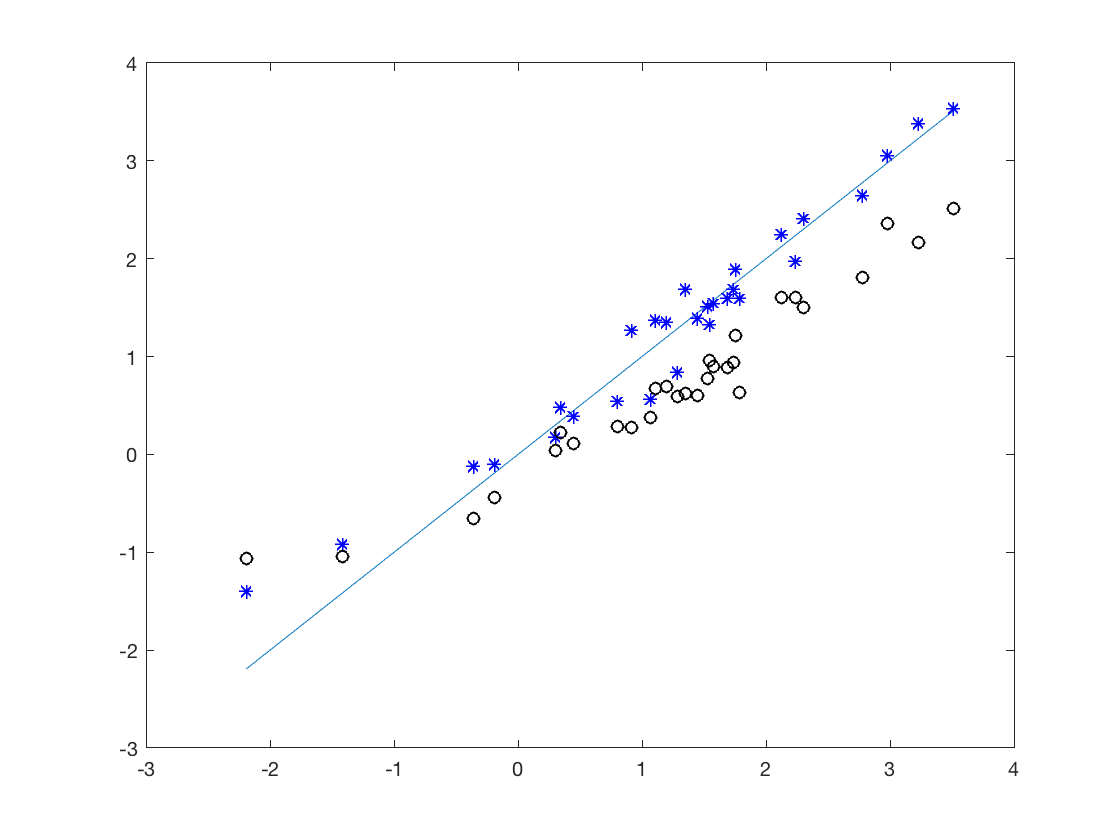

norm_exp = exp_true - exp_true(1);
plot (norm_exp, norm_exp, norm_exp(2:S), PPML(1:S-1,1), 'b*',...
    norm_exp(2:S),OLS(1:S-1,1),'ko');

Now we would normally repeat another 1000 times 

# Tetrad Method and Calibration

X is our trade flows, observable symmetric component of trade costs SC, and observable wages w. All a_ij = 1. A is from armingon_data, 

Our mission, should we choose to accept it, is to estimate $ln(\tau_{ij}) = ln(sc_{ij})+ac_i$

With trade share $\pi_{ij} = \frac{X_{ij}}{Y_{j}} = (A_i^{\sigma-1}w_i^{1-\sigma})\times(a_{ij}\tau_{ij}^{1-\sigma})\times P_j^{\sigma-1}$ and within a country has unit frictions , thus $\pi_{jj} =(A_j^{\sigma-1}w_j^{1-\sigma})\times P_j^{\sigma-1}$. ac_i is z_i

## The Tetrad


$$\frac{\pi_{ij}}{\pi_{jj}} = \frac{(A_i^{\sigma-1}w_i^{1-\sigma})\times (a_{ij}\tau_{ij}^{1-\sigma})}{(A_j^{\sigma-1}w_j^{1-\sigma})} = e^{exp_i+\gamma ln(distance_{ij}) + \beta ln(border_{ij})+z_i -imp_j}$$


with Sx1 constraints exp_i=-imp_j whenever i=j (so that z_i isn't colinear with exp_i)

clc;
load 'tetrad_data.mat';
a_ij = ones(S,S);

while tolerance > 0.00001
   
    Y = w.*L;
    
    P =  sum(( a_ij.*repmat(A.^(sigma-1),1,S) .* ...
        (tau_ij.*repmat(w,1,S)).^(1-sigma) ),1)'.^(1./(1-sigma));
    
    X = repmat(A.^(sigma-1),1,S).* repmat(w.^(1-sigma),1,S) .* a_ij .* ...
        tau_ij.^(1-sigma) .* repmat( (Y.*P.^(sigma-1))', S,1);
    
    new_w = sum(X,2)./L;
    
    new_w = new_w./new_w(1); % numeraire country is first entry
    
    tolerance = (w-new_w)'*(w-new_w); % could also use sum of squares
    % try to stay close to something nice and boring and well known
    
    %disp(['tolerance = ', num2str(tolerance)]); % literally watch tolerance   
    
    w = w.*(1-update) + new_w.*update; % weighted average to update w
    % w = new_w may make system unstable
    
end
